# L4 - Ex 2-  Ariadna Cortés Danés

clear all
format long

Genereu 20 punts de la forma $ (x_i,y_i)$ tals que $y_i=J_0(x_i)$, on $J_0(x)=\frac{1}{\pi }\int^\pi _0cos(x sint)dt $ la funció de Bessel d’ordre zero i les $x_i
$ són de l’interval $[-3,3]$ i equiespaiades. Utilitzeu la funció **besselj****(0,**$x_i
$**)** de  Matlab®

x = linspace(-3,3,20)

x =   -3.000000000000000  -2.684210526315789  -2.368421052631579  -2.052631578947369  -1.736842105263158  -1.421052631578947  -1.105263157894737  -0.789473684210526  -0.473684210526316  -0.157894736842105   0.157894736842105   0.473684210526316   0.789473684210526   1.105263157894737   1.421052631578947   1.736842105263158   2.052631578947369   2.368421052631579   2.684210526315789   3.000000000000000


y = besselj(0,x)

y =   -0.260051954901934  -0.135438748307326   0.019039611658932   0.193635835560305   0.376662760411042   0.555406474467033   0.717139555505670   0.850148504822509   0.944687570784899   0.993777017893277   0.993777017893277   0.944687570784899   0.850148504822509   0.717139555505670   0.555406474467033   0.376662760411042   0.193635835560305   0.019039611658932  -0.135438748307326  -0.260051954901934


mesh = linspace(-3,3,20) + 0.15;     % malla utilitzada per evaluar l'error del polinomi en els punts intermitjos



### **(a)**

Calculeu l’aproximació per mínims quadrats d’aquest conjunt de punts emprant polinomis de grau des de 1 fins a 10. 

- Estudieu l’error que es produeix avaluant els polinomis de punts intermedis (entre $t_i$ i $t_{i-1}$) i comparant el resultat amb el seu valor exacte. Obteniu el residu acumulat en aquests punts. 

- Quin seria el millor model? Consulteu l'article [Finding the optimum polynomial order to use for regression](https://autarkaw.org/2008/07/05/finding-the-optimum-polynomial-order-to-use-for-regression/).   Per cada polinomi, calculeu el residu i el paramètre definit en l'article referenciat; raoneu els resultats obtinguts i argumenteu l'elecció del polinomi. 

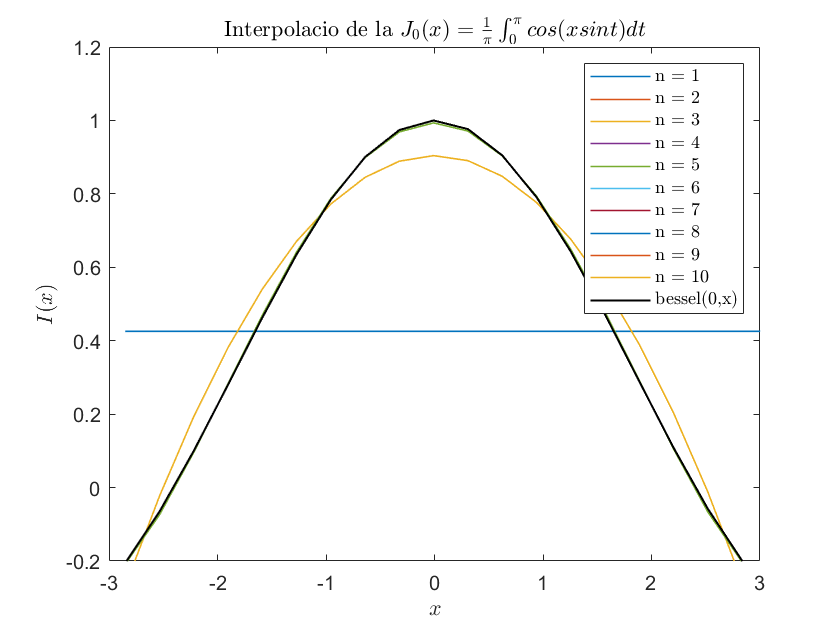

close all;
Sr1 = [];   
var1 = [];
%sum of the square of the residuals for the mth order polynomial
for n = 1:10
    V = fliplr(vander(x));  % genera la matriu que ens permetrà resoldre el sistema
    V = V(:, 1:n+1);        % ens quedem nomes amb les primeres n + 1 columnes
    
    a = V\y';
    % Crea la matriu de Vandermonde per la malla per evaluar el polinomi
     X = fliplr(vander(mesh));
     X = X(:, 1:n+1);
     
     % Plot de l'aproximació polinomica
     figure(1);
     plot(mesh, X*a, 'Linewidth',0.8)
     hold on;
     
     % Calcul del residu 
     res = besselj(0,mesh)' - X*a; 
     aux = sum(res.^2);
     Sr1 = [Sr1 aux];
     var1 = [var1 aux/(20-n-1)];
end

title('Interpolacio de la $J_0(x)=\frac{1}{\pi }\int^\pi _0cos(x sint)dt$', 'Interpreter', 'latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$I(x)$', 'Interpreter', 'latex')
plot(mesh,besselj(0,mesh), "-k", 'LineWidth',1)
legend("n = 1", "n = 2","n = 3","n = 4","n = 5","n = 6","n = 7","n = 8","n = 9","n = 10", "bessel(0,x)", 'Interpreter', 'latex')
axis([-3 3 -0.2 1.2])
hold off;

### **(b)** 

Com que la funció de Bessel $J_0(x)$ és una funció parell, calculeu l’aproximació per polinomis només amb termes parell, és a dir, de la forma $erf(t)\approx c_0+c_1\cdot x^2+c_2x^4+\cdots +c_n \cdot x^{2n}$ . Feu, també, una estimació de l’error produit similar a l'apartat anterior.

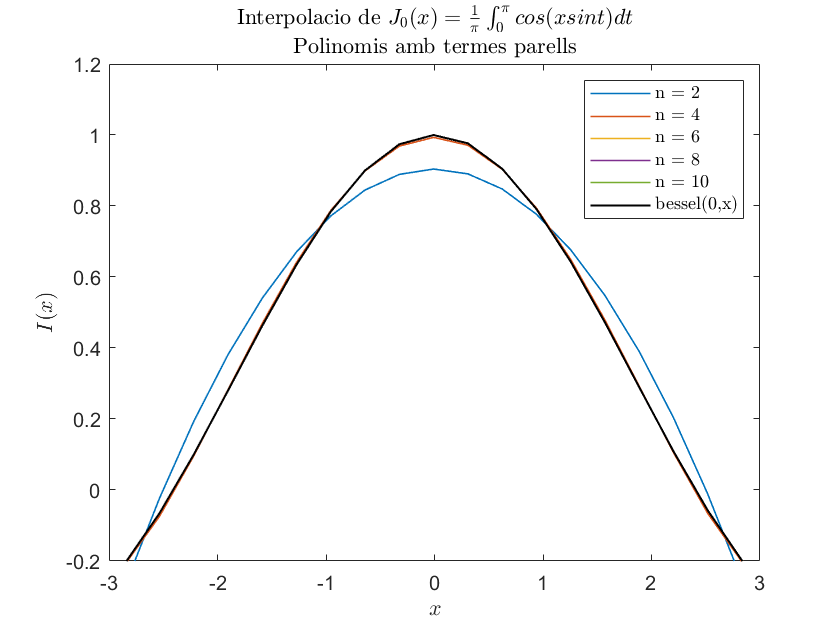

% Repetirem el mateix procés només per ns parells
close all;
Sr2 = [];
var2 = [];
for n = 2:2:10
    V = fliplr(vander(x));  % genera la matriu que ens permetrà resoldre el sistema
    V = V(:, 1:2:n+1);        % ens quedem nomes amb les primeres n + 1 columnes, treient les imparelles
    
    a = V\y';
    % Crea la matriu de Vandermonde per la malla per evaluar el polinomi
     X = fliplr(vander(mesh));
     X = X(:, 1:2:n+1);        %nomes agafa les columnes corresponents a exponents parells
     
     % Plot de l'aproximació polinomica
     figure(2);
     plot(mesh, X*a, 'Linewidth',0.8)
     hold on;
     
     % Calcul del residu 
     res = besselj(0,mesh)' - X*a; 
     aux = sum(res.^2);
     Sr2 = [Sr2 aux];
     var2 = [var2 aux/(20-n-1)];
     
end

title('Interpolacio de $J_0(x)=\frac{1}{\pi }\int^\pi _0cos(x sint)dt$', 'Interpreter', 'latex')
subtitle('Polinomis amb termes parells', 'Interpreter', 'latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$I(x)$', 'Interpreter', 'latex')
plot(mesh,besselj(0,mesh), "-k", 'LineWidth',1)
legend("n = 2", "n = 4","n = 6","n = 8","n = 10", "bessel(0,x)", 'Interpreter', 'latex')
axis([-3 3 -0.2 1.2])
hold off;

### **(c)** 

Finalment, calculeu l’aproximació del conjunt de punts sota el criteri de mínims quadrats i per un polinomi del tipus $$J_0(x)\approx c_0+c_1(x/3)^2+c_2(x/3)^4+\cdots +c_n(x/3)^{2n}$$. Estudieu com es comporta l’error per a aquesta nova aproximació i compareu aquest resultat amb els anteriors.

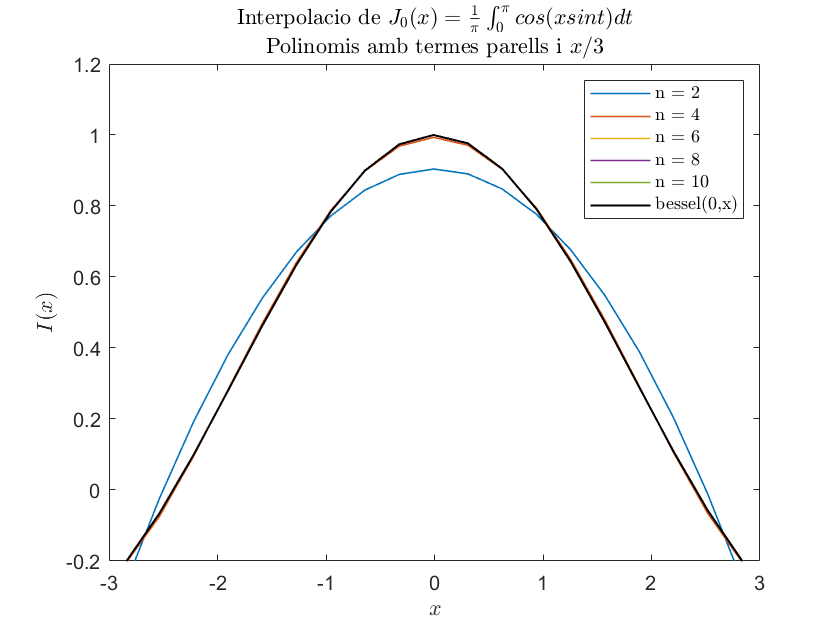

% Repetirem el mateix procés dividint x entre 1/3
close all;
Sr3 = [];
var3 = [];
for n = 2:2:10
    V = fliplr(vander(x/3));  % genera la matriu que ens permetrà resoldre el sistema
    V = V(:, 1:2:n+1);        % ens quedem nomes amb les primeres n + 1 columnes, en posicions d'exponent parell
    
    a = V\y';
    % Create the Vandermonde matrix for a mesh to evaluate the polynomial
     X = fliplr(vander(mesh/3));
     X = X(:, 1:2:n+1);
     
     % Plot de l'aproximació polinomica
     figure(2);
     plot(mesh, X*a, 'Linewidth',0.8)
     hold on;
     
     %Calcul de l'error
     res = besselj(0,mesh)' - X*a; 
     aux = sum(res.^2);
     Sr3 = [Sr3 aux];
     var3 = [var3 aux/(20-n-1)];
end

title('Interpolacio de $J_0(x)=\frac{1}{\pi }\int^\pi _0cos(x sint)dt$', 'Interpreter', 'latex')
subtitle('Polinomis amb termes parells i $x/3$', 'Interpreter', 'latex')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$I(x)$', 'Interpreter', 'latex')
plot(mesh,besselj(0,mesh), "-k", 'LineWidth',1)
legend("n = 2", "n = 4","n = 6","n = 8","n = 10", "bessel(0,x)", 'Interpreter', 'latex')
axis([-3 3 -0.2 1.2])
hold off;

### **(d) **

Presenteu els resultats de cada apartat en una taula.  Comenteu i argumenteu els resultats obtinguts.

n1 = 1:1:10;
table(n1',Sr1', var1', 'VariableNames',["n", "S(r)", "S(r)/(n-m-1)"])

ans = 10×3 table
    n             S(r)                S(r)/(n-m-1)    
    __    ____________________    ____________________

     1        3.79072568352299       0.210595871306833
     2       0.143086883803958     0.00841687551787987
     3       0.143086883803958     0.00894293023774737
     4     0.00106867076806579     7.1244717871053e-05
     5     0.00106867076806579    7.63336262904135e-05
     6    3.19036541834705e-06    2.45412724488234e-07
     7    3.19036541835222e-06    2.65863784862685e-07
     8    6.13942374869378e-09    5.58129431699435e-10
     9    6.13942374856594e-09    6.13942374856594e-10
    10    8.99105255534307e-12    9.99005839482564e-13


n2 = 2:2:10;
table(n2',Sr2', var2', 'VariableNames',["n", "S(r)", "S(r)/(n-m-1)"])

ans = 5×3 table
    n             S(r)                S(r)/(n-m-1)    
    __    ____________________    ____________________

     2       0.143086883803958     0.00841687551787987
     4     0.00106867076806581    7.12447178710542e-05
     6     3.1903654183451e-06    2.45412724488085e-07
     8    6.13942374865492e-09    5.58129431695902e-10
    10    8.99105256348478e-12    9.99005840387198e-13


n2 = 2:2:10;
table(n2',Sr3', var3', 'VariableNames',["n", "S(r)", "S(r)/(n-m-1)"])

ans = 5×3 table
    n             S(r)                S(r)/(n-m-1)    
    __    ____________________    ____________________

     2       0.143086883803958     0.00841687551787988
     4     0.00106867076806578     7.1244717871052e-05
     6    3.19036541834896e-06    2.45412724488381e-07
     8    6.13942374865737e-09    5.58129431696125e-10
    10    8.99105257764273e-12    9.99005841960303e-13


Si obvservem les taules, verurem que per un mateix grau de polinomi, tots els residus valen el mateix. Aquest fet es deu a la paritat de la nostra funció (Besselj). Com que aquesta funció és parell, els termes de grau senar sempre tenen coeficients nuls i, per tant, el polinomi sencer i el polinomi en termes parells son exactament el mateix. Per aquest motiu, no veiem cap variació en el valor dels residus.